clc; clear all; close all;
syms phi theta phi_dot theta_dot phi_ddot theta_ddot phi_ref theta_ref theta0 phi0
syms t tau
syms l_p l_w m_w m_p g k_phi k_theta d_theta d_phi x x_ddot x_dot J_p J_w d_thetadot d_phidot Q_phi Q_theta real
q = [theta ; phi] 

$$q = \left(\begin{array}{c} \theta \\ \varphi \end{array}\right)$$

qdot =[theta_dot; phi_dot] 

$$qdot = \left(\begin{array}{c} \dot{\theta }\\ \dot{\varphi } \end{array}\right)$$

qddot = [theta_ddot; phi_ddot]

$$qddot = \left(\begin{array}{c} \ddot{\theta }\\ \ddot{\varphi } \end{array}\right)$$

q0 = [theta0;phi0];
w_angle = [0;0;theta+phi]

$$w\_angle = \left(\begin{array}{c} 0\\ 0\\ \varphi +\theta \end{array}\right)$$

p_angle = [0;0;theta];
r1 = [x;0;0]

$$r1 = \left(\begin{array}{c} x\\ 0\\ 0 \end{array}\right)$$

r2 = [x + l_w*cos(theta); l_w*sin(theta);0]

$$r2 = \left(\begin{array}{c} x+l_{w}\,\cos\left(\theta \right)\\ l_{w}\,\sin\left(\theta \right)\\ 0 \end{array}\right)$$

r3 = [x - l_p*cos(theta); l_p*sin(theta);0];
r1_dot = [x_dot;0;0] 

$$r1\_dot = \left(\begin{array}{c} \dot{x}\\ 0\\ 0 \end{array}\right)$$

r2_dot = jacobian(r2,q)*qdot+r1_dot

$$r2\_dot = \left(\begin{array}{c} \dot{x}-l_{w}\,\dot{\theta }\,\sin\left(\theta \right)\\ l_{w}\,\dot{\theta }\,\cos\left(\theta \right)\\ 0 \end{array}\right)$$

r3_dot = jacobian(r3,q)*qdot+r1_dot;
T = J_w * (theta_dot + phi_dot)^2 / 2 + J_p * theta_dot^2 / 2 +  m_p * ((x_dot- theta_dot * l_p * sin(theta))^2 + (theta_dot^2 * l_p^2 * cos(theta)^2)) /2 + m_w * ((x_dot - theta_dot * l_w * sin(theta))^2 + (theta_dot^2 * l_w^2 *cos(theta)^2))/2;
M2 = [0;0;tau - d_phi*phi_dot], M3 = [0;0;d_phi*phi_dot-tau - d_theta*theta_dot];

$$M2 = \left(\begin{array}{c} 0\\ 0\\ \tau -d_{\varphi }\,\dot{\varphi } \end{array}\right)$$

jacobian(w_angle,q);
jacobian(p_angle,q);
Q2 = jacobian(w_angle,q).'*M2, Q3 = jacobian(p_angle,q).'*M3;

$$Q2 = \left(\begin{array}{c} \tau -d_{\varphi }\,\dot{\varphi }\\ \tau -d_{\varphi }\,\dot{\varphi } \end{array}\right)$$

Q = [Q_theta; Q_phi];            % Generalized forces
Q = simplify(Q2+Q3);

# All matrixes

% Define substitution values
subs_values = struct( ...
    'k_theta', 6.558, ...
    'k_phi', 0.114, ...
    'theta_ref', pi / 2, ...
    'phi_ref', 0.0, ...
    'g', 9.81, ...
    'm_p', 1.0, ...
    'l_p', 0.5, ...
    'm_w', 0.2, ...
    'l_w', 1.0, ...
    'd_theta' , 0 ,...
    'd_phi' , 0, ...
    'J_p' , 0.083,...
    'tau',0,...
    'J_w' , 0.1...
);
% Define potential energy terms
Uk = 0.5 * k_theta * (theta - theta_ref)^2 + 0.5 * k_phi * (phi - phi_ref)^2; % Spring potential energy
Vg = m_p * g * l_p * sin(theta) + m_w * g * l_w * sin(theta);                % Gravitational potential energy
V = Uk + Vg % Total potential energy

$$V = \frac{k_{\varphi }\,{\left(\varphi -\varphi_{\mathrm{ref}}\right)}^{2}}{2}+\frac{k_{\theta }\,{\left(\theta -\theta_{\mathrm{ref}}\right)}^{2}}{2}+g\,l_{p}\,m_{p}\,\sin\left(\theta \right)+g\,l_{w}\,m_{w}\,\sin\left(\theta \right)$$


% Partial derivatives of potential energy
V_transpose_partialderivative = jacobian(V, q).';
% Substitute numeric values in potential energy derivative
V_numeric = subs(V_transpose_partialderivative, subs_values);

% Define mass matrix
T = 0.5 * m_p * l_p^2 * theta_dot^2 + 0.5 * m_w * l_w^2 * phi_dot^2; % Kinetic energy (example)
M0 = simplify(jacobian(jacobian(T, qdot).', qdot)); % Mass matrix

% Substitute numeric values in mass matrix and stiffness matrix
M0 = subs(M0, subs_values)

$$M0 = \left(\begin{array}{cc} \frac{1}{4} & 0\\ 0 & \frac{1}{5} \end{array}\right)$$

K0=[0.60953694975053103444350827304431, 0; sym(0), 0.114]

$$K0 = \left(\begin{array}{cc} \frac{5490220759530081}{9007199254740992} & 0\\ 0 & \frac{57}{500} \end{array}\right)$$


% Check damping and non-conservative force matrices
D0 = zeros(size(M0)); % No damping
K0Q = zeros(size(M0)); % No non-conservative forces (Q assumed zero)

% Linearized equations of motion
LinEOM = M0 * qddot + D0 * qdot + (K0 + K0Q) * q == Q;

## Question a)

 Determine the eigenfrequencies ω1 and ω2, with 0 ≤ ω1 ≤ ω2, and the corresponding eigenvectors u1 and u2 of the undamped system. Do this, by using the eig function in Matlab. Normalize u1 and u2 such that their first entries (related to the first DOF) equal 1. 

% Define identity and zero matrices for state-space representation
I = eye(size(M0));
Zero = zeros(size(M0));

% Compute M0 inverse
M0_inv = inv(M0)

$$M0\_inv = \left(\begin{array}{cc} 4 & 0\\ 0 & 5 \end{array}\right)$$


% Define the system matrix A
%A = [Zero, I; -M0_inv * (K0 + K0Q), -M0_inv * D0]
M0 = double(vpa(M0))

M0 =     0.2500         0
         0    0.2000


K0 = double(vpa(K0))

K0 =     0.6095         0
         0    0.1140



% Compute eigenvalues and eigenvectors of the system matrix
[eigevectors,eigenvalues]=eig(M0/K0); % MATLAB's eigenvale and eigenvector solver.
w=sqrt(diag(eigenvalues));            % Calculating the natural frequencies
fprintf('  Eigenfequencies: ');

  Eigenfequencies: 

w1 = w(1)                     % 1st eigenfrequency

w1 = 0.6404

w2 = w(2)                     % 2nd eigenfrequency

w2 = 1.3245

 % Display results
fprintf('Eigenvalues:\n');        

Eigenvalues:


for i = 1:length(eigenvalues)
    fprintf('  Eigenvalue %d: %.4f + %.4fi\n', ...
            i, real(eigenvalues(i)), imag(eigenvalues(i)));
end

  Eigenvalue 1: 0.4101 + 0.0000i
  Eigenvalue 2: 0.0000 + 0.0000i




for i = 1:length(eigenvalues)
    fprintf('  Eigenvector corresponding to Eigenvalue %d:\n', i);
    fprintf('    [');
    fprintf(' %.4f + %.4fi ', real(eigevectors(:,i)), imag(eigevectors(:,i)));
    %fprintf(' %.4f + %.4fi ', real(eigenvectors(:,i)), imag(eigenvectors(:,i)));
    fprintf(']\n');
end

  Eigenvector corresponding to Eigenvalue 1:


    [

 1.0000 + 0.0000i  0.0000 + 0.0000i 

]


  Eigenvector corresponding to Eigenvalue 2:


    [

 0.0000 + 1.0000i  0.0000 + 0.0000i 

]


## Question b)

Generate a time trajectory with the set of undamped linear equations for four different simulation conditions. Please consider the initial relative positions: • q 1 (0) = 0 0.12⊤ • q 1 (0) = 0.024 0.108⊤ • q 1 (0) = 0.06 −0.8593 −1.603⊤ (hint: this choice for q 1 (0) is proportional to modeshape u1 .) • q 1 (0) = 0.027 −1.066 3.051⊤ (hint: this choice for q 1 (0) is proportional to modeshape u2 .) in combination with ˙q 1 (0) = 0 0⊤ , τ(t) = 0 and a simulation time of 200 seconds. Add the following plot to the answerform_3.docx document: • A plot with the relative angle between the pendulum arm and the unit vector ⃗ex θ1(t) on the x-axis and the relative angle between the reaction wheel and the pendulum arm ϕ1(t) on the y-axis. In other words, your plot should contain all four trajectories of the relative coordinates q 1 (t). The x-axis should show the interval −0.066 0.066 rad and the y-axis the interval −0.17 0.17 rad. In addition, include a title, appropriate labels for both axes, and a legend. Make sure that all four trajectories can be distinguished. 

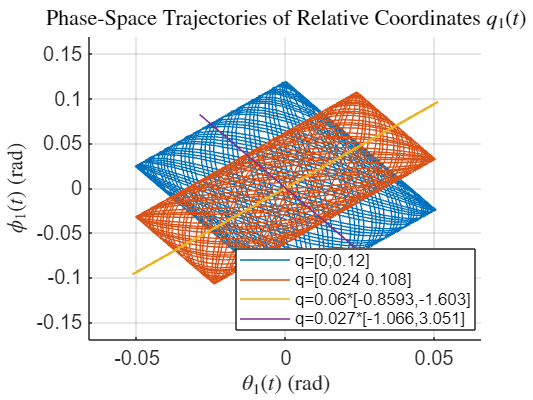

%Parameters
g = 9.81;          % Gravitational acceleration (m/s^2)
Lp = 0.5;          % Length of the pendulum (m)
Lw = 1;            % Length of the reaction wheel (m)
Mp = 1;            % Mass of the pendulum (kg)
Mw = 0.2;          % Mass of the reaction wheel (kg)
Jp = 0.083;        % Moment of inertia of the pendulum (kg·m^2)
Jw = 0.1;          % Moment of inertia of the reaction wheel (kg·m^2)
ktheta = 6.558;    % Stiffness constant 
kphi = 0.114;      % Stiffness constant 


% Mass matrix
M = [Mp*Lp^2 + Mw*Lw^2 + Jp + Jw, Jw;
     Jw, Jw];

% Stiffness matrix
K = [ktheta - 0.5*sqrt(3)*g*(Lp*Mp + Lw*Mw), 0;
     0, kphi];

% Compute M^(-1) * K
Minv = inv(M);
MinvK = Minv * K;

% Undamped system matrix
A = [zeros(2), eye(2);
     -MinvK, zeros(2)];

% Simulation parameters
t_span = [0, 200]; % Time span for simulation (0 to 200 seconds)
num_points = 1000; % Number of time points
t_eval = linspace(t_span(1), t_span(2), num_points); % Time vector

% Define the system dynamics (dx/dt = A*x)
dynamics = @(t, x) A * x;

% Initial conditions
initial_conditions = [
    [0, 0.12, 0, 0];
    [0.024, 0.108, 0, 0];
    [0.06 * -0.8593, 0.06 * -1.603, 0, 0]; % Proportional to mode shape u1
    [0.027 * -1.066, 0.027 * 3.051, 0, 0]  % Proportional to mode shape u2
];

% Colors for plotting
colors = lines(size(initial_conditions, 1));

% Preallocate results
trajectories = cell(size(initial_conditions, 1), 1);

% Simulate the system for each initial condition
for i = 1:size(initial_conditions, 1)
    % Solve the system using ode45
    [T, X] = ode45(dynamics, t_span, initial_conditions(i, :));
    trajectories{i} = X; % Store trajectory
end

% Plot phase-space trajectories
figure;
hold on;
x_limits = [-0.066, 0.066];
y_limits = [-0.17, 0.17];

for i = 1:length(trajectories)
    % Extract q1 = [theta; phi]
    theta = trajectories{i}(:, 1);
    phi = trajectories{i}(:, 2);
    plot(theta, phi );
end
legend({'q=[0;0.12]','q=[0.024 0.108]',  'q=0.06*[-0.8593,-1.603]', 'q=0.027*[-1.066,3.051]'}, 'FontSize', 10);
title('Phase-Space Trajectories of Relative Coordinates $q_1(t)$', 'Interpreter', 'latex');
xlabel('$\theta_1(t)$ (rad)', 'Interpreter', 'latex');
ylabel('$\phi_1(t)$ (rad)', 'Interpreter', 'latex');
xlim(x_limits);
ylim(y_limits);
legend('Location', 'best');
grid on;
set(gca, 'FontSize', 12);
hold off;

## Question d)

Simulate the nonlinear equations of motion using the input signal τ(t) = 0.01sin(ω2t), where ω2 denotes the highest eigenfrequency obtained in question a above, by utilizing Simulink. Please consider the initial position and velocity q(0) = 1 3 π 1 2 π ⊤ , ˙q(0) = 0 0⊤ , prescribed displacement spd(t) = 0 and a simulation time of 35 seconds. Add the following 2 plots to the answerform_3.docx document: • A plot with time on the x-axis and the angle between the pendulum arm and the unit vector ⃗ex θ(t) on the y-axis. The x-axis should show the interval 0 35 s and the y-axis the interval 1.028 1.072 rad. In addition, include a title, and appropriate labels for both axes. • A plot with time on the x-axis and the angle between the reaction wheel and the pendulum arm ϕ(t) on the y-axis. The x-axis should show the interval 0 35 s and the y-axis the interval 1.529 1.621 rad. In addition, include a title, and appropriate labels for both axes. 

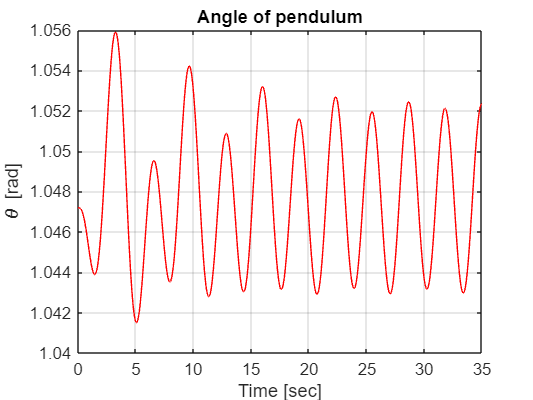

%% Run Simulation and save results
results = sim('Simulink_demo_2024.slx', 'StopTime', '35');

% Restructure q into 2 columns
results.q = squeeze(results.q)';
%% Plot the results
figure(1)
plot(results.tout,results.q(:,1),'r')
grid on

xlabel('Time [sec]')
ylabel('\theta [rad]')
title('Angle of pendulum')

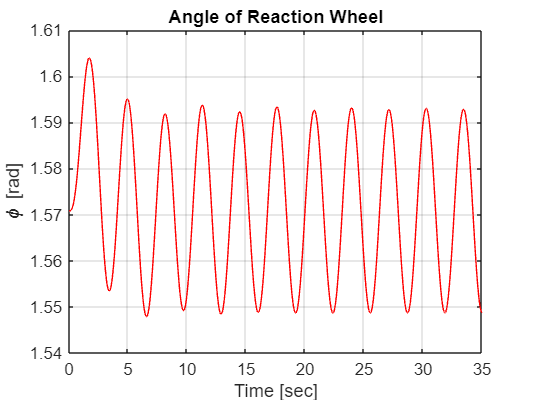


figure(2)
plot(results.tout,results.q(:,2),'r')
grid on

xlabel('Time [sec]')
ylabel('\phi [rad]')
title('Angle of Reaction Wheel')

## Question f)

Compute the damped transfer functions G1(s) and G2(s) as defined above using the linear equations of motion around the stable equilibrium position q 0 from question c of deliverable 2, i.e., with damping. Add the bode diagrams of these transfer functions to the answerform_3.docx document

% Improved MATLAB Code for Computing and Plotting Bode Diagrams

% Define symbolic variables
syms s tau
syms mp lp Jp mw lw Jw d_theta d_phi k_theta k_phi

% Define numerical values for parameters (adjust these values as needed)
subs_values = struct( ...
    'k_theta', 6.558, ...
    'k_phi', 0.114, ...
    'theta_ref', pi / 2, ...
    'phi_ref', 0.0, ...
    'g', 9.81, ...
    'm_p', 1.0, ...
    'l_p', 0.5, ...
    'm_w', 0.2, ...
    'l_w', 1.0, ...
    'd_theta' , 0 ,...
    'd_phi' , 0, ...
    'J_p' , 0.083,...
    'J_w' , 0.1...
);

% Define matrice D
D = [d_theta, 0;
     0, d_phi];

% Define input torque vector Q (normalized for transfer function derivation)
Q = [0; 1];

% Equation of motion in Laplace domain
lhs = M * s^2 + D * s + K; % System matrix in Laplace domain
q_s = simplify(lhs \ Q);   % Solve for q(s)

fprintf('[G1 and G2] is equal to')

[G1 and G2] is equal to

% Extract symbolic transfer functions
G_sym = [simplify(q_s(1)); simplify(q_s(2))] % [G1(s); G2(s)]

$$G\_sym = \begin{array}{l} \left(\begin{array}{c} -\frac{879609302220800000\,s^{2}}{\sigma_{1}}\\ \frac{500\,\left(11135853766115328\,s^{2}+17592186044416000\,d_{\theta }\,s+10748888164317125\right)}{\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=5374444082158562500\,d_{\varphi }\,s+1002754604531712000\,d_{\theta }\,s+5567926883057664000\,d_{\varphi }\,s^{3}+879609302220800000\,d_{\theta }\,s^{3}+1172188072884429946\,s^{2}+468831758083686400\,s^{4}+8796093022208000000\,d_{\varphi }\,d_{\theta }\,s^{2}+612686625366076125 \end{array}$$

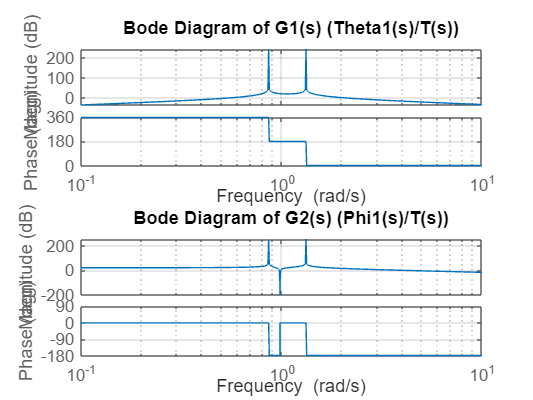


% Substitute numerical values into transfer functions
G_num = subs(G_sym, subs_values); % Substitute parameter values


% Convert symbolic transfer functions to numerical transfer functions
transfer_functions = cell(2, 1); % Store transfer functions (G1, G2)
for i = 1:2
    [num, den] = numden(G_num(i)); % Extract numerator and denominator
    transfer_functions{i} = tf(sym2poly(num), sym2poly(den)); % Convert to transfer function
end

% Plot Bode diagrams for G1(s) and G2(s)
figure;
titles = {'Bode Diagram of G1(s) (Theta1(s)/T(s))', ...
          'Bode Diagram of G2(s) (Phi1(s)/T(s))'};

for i = 1:2
    subplot(2, 1, i);
    bode(transfer_functions{i}); % Plot Bode diagram
    grid on;
    title(titles{i});
end


% Display transfer functions
disp('Transfer Functions:');

Transfer Functions:


disp('G1(s) = ');

G1(s) = 


disp(transfer_functions{1});

  tf with properties:

       Numerator: {[0 0 -8.7961e+17 0 0]}
     Denominator: {[4.6883e+17 0 1.1722e+18 0 6.1269e+17]}
        Variable: 's'
         IODelay: [0]
      InputDelay: [0]
     OutputDelay: [0]
       InputName: {''}
       InputUnit: {''}
      InputGroup: [1×1 struct]
      OutputName: {''}
      OutputUnit: {''}
     OutputGroup: [1×1 struct]
           Notes: [0×1 string]
        UserData: []
            Name: ''
              Ts: [0]
        TimeUnit: 'seconds'
    SamplingGrid: [1×1 struct]



disp('G2(s) = ');

G2(s) = 


disp(transfer_functions{2});

  tf with properties:

       Numerator: {[0 0 5.5679e+18 0 5.3744e+18]}
     Denominator: {[4.6883e+17 0 1.1722e+18 0 6.1269e+17]}
        Variable: 's'
         IODelay: [0]
      InputDelay: [0]
     OutputDelay: [0]
       InputName: {''}
       InputUnit: {''}
      InputGroup: [1×1 struct]
      OutputName: {''}
      OutputUnit: {''}
     OutputGroup: [1×1 struct]
           Notes: [0×1 string]
        UserData: []
            Name: ''
              Ts: [0]
        TimeUnit: 'seconds'
    SamplingGrid: [1×1 struct]



## Question g)

Determine the gains |G1(jω2)| and |G2(jω2)|. Are these values similar to the amplification that you observed in question d? 

% Calculate DC gain (s = 0)
DC_gains = zeros(2, 1); % Array to store DC gains for G1(s) and G2(s)

for i = 1:2
    DC_gains(i) = dcgain(transfer_functions{i}); % MATLAB's dcgain function computes gain at s=0
end

% Display DC gains
disp('DC Gains:');

DC Gains:


disp(['DC Gain of G1(s): ', num2str(DC_gains(1))]);

DC Gain of G1(s): 0


disp(['DC Gain of G2(s): ', num2str(DC_gains(2))]);

DC Gain of G2(s): 8.7719


frequencies = 1.3245; % Define the frequencies in rad/s
gains_at_freqs = zeros(2, length(frequencies)); % Store gain for G1 and G2 at each frequency

for i = 1:2
    [mag, ~, ~] = bode(transfer_functions{i}, frequencies); % Compute magnitude at specific frequencies
    gains_at_freqs(i, :) = squeeze(mag); % Extract magnitude values
end

% Display gains at specific frequencies
disp('Gain Magnitudes at Specific Frequencies:');

Gain Magnitudes at Specific Frequencies:


for i = 1:2
    for j = 1:length(frequencies)
        fprintf('Gain of G%d(s) at %d rad/s: %.4f\n', i, frequencies(j), gains_at_freqs(i, j));
    end
end

Gain of G1(s) at 1.324500e+00 rad/s: 1879.6572
Gain of G2(s) at 1.324500e+00 rad/s: 5351.5902
